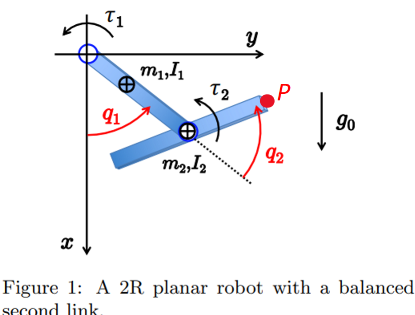

syms q1 q2 q3 l1 l2 l3 m1 m2 m3 d1 d2 d3  I1 I2 I3 g0 real
syms dq1 dq2 dq3 ddq1 ddq2 real

%% Kinetic energy of joint 1
x1 = d1*cos(q1);
y1 = d1*sin(q1);
z1 = q1;

vx1 = diff(x1, q1)*dq1 + diff(x1, q2)*dq2 + diff(x1, q3)*dq3;
vy1 = diff(y1, q1)*dq1 + diff(y1, q2)*dq2 + diff(y1, q3)*dq3;
vz1 = diff(z1, q1)*dq1 + diff(z1, q2)*dq2 + diff(z1, q3)*dq3;

T1 = 0.5*m1*[vx1 vy1 0]*[vx1; vy1; 0;]+0.5*I1*[0 0 vz1]*[0; 0; vz1;];

disp('velocity of joint 1: ');

velocity of joint 1: 


disp([vx1; vy1; vz1;]);

$$\left(\begin{array}{c} -d_{1}\,{\mathrm{dq}}_{1}\,\sin\left(q_{1}\right)\\ d_{1}\,{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\\ {\mathrm{dq}}_{1} \end{array}\right)$$


disp('Kinetic Energy of joint 1: ');

Kinetic Energy of joint 1: 


disp(T1);

$$\frac{m_{1}\,{d_{1}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{m_{1}\,{d_{1}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}}{2}+\frac{I_{1}\,{{\mathrm{dq}}_{1}}^{2}}{2}$$


%% Kinetic energy of joint 2
x2 = l1*cos(q1);
y2 = l1*sin(q1);
z2 = q1+q2;

vx2 = diff(x2, q1)*dq1 + diff(x2, q2)*dq2 + diff(x2, q3)*dq3;
vy2 = diff(y2, q1)*dq1 + diff(y2, q2)*dq2 + diff(y2, q3)*dq3;
vz2 = diff(z2, q1)*dq1 + diff(z2, q2)*dq2 + diff(z2, q3)*dq3;

T2 = 0.5*m2*[vx2 vy2 0;]*[vx2; vy2; 0;] + 0.5*I2*[0 0 vz2;]*[0; 0; vz2;];

disp('velocity of joint 2: ');

velocity of joint 2: 


disp([vx2; vy2; vz2;]);

$$\left(\begin{array}{c} -{\mathrm{dq}}_{1}\,l_{1}\,\sin\left(q_{1}\right)\\ {\mathrm{dq}}_{1}\,l_{1}\,\cos\left(q_{1}\right)\\ {\mathrm{dq}}_{1}+{\mathrm{dq}}_{2} \end{array}\right)$$


disp('Kinetic Energy of joint 2: ');

Kinetic Energy of joint 2: 


disp(T2);

$$\frac{I_{2}\,{\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}\,{\cos\left(q_{1}\right)}^{2}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}\,{\sin\left(q_{1}\right)}^{2}}{2}$$


T = simplify(T1 + T2, Steps=1000);
disp("Total Kinetic Energy: ");

Total Kinetic Energy: 


disp(T);

$$\frac{I_{2}\,{\left({\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}\right)}^{2}}{2}+\frac{I_{1}\,{{\mathrm{dq}}_{1}}^{2}}{2}+\frac{{d_{1}}^{2}\,{{\mathrm{dq}}_{1}}^{2}\,m_{1}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,{l_{1}}^{2}\,m_{2}}{2}$$


%% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);
M12 = diff(diff(T, dq1), dq2);

M21 = diff(diff(T, dq2), dq1);
M22 = diff(diff(T, dq2), dq2);

M31 = diff(diff(T, dq3), dq1);
M32 = diff(diff(T, dq3), dq2);

M = [M11, M12;
     M21, M22;];

M = simplify(M);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$\left(\begin{array}{cc} m_{1}\,{d_{1}}^{2}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2} & I_{2}\\ I_{2} & I_{2} \end{array}\right)$$


%% CORIOLIS/CENTRIFUGAL VECTOR c(q,dq)
% using the Christoffel symbols for a 3-DOF system
q  = [q1; q2;];
dq = [dq1; dq2;];

% Inizializza la matrice C(q, dq) (2x2) a zeri simbolici:
C = sym(zeros(2,2));

% Formula dei coefficienti di Christoffel (Robotics):
%   C(i,j) = 1/2 * SUM_k [ dM(i,j)/dq_k + dM(i,k)/dq_j - dM(k,j)/dq_i ] * dq_k
% Poi il vettore c(q,dq) = C(q,dq) * dq
for i = 1:2
    for j = 1:2
        % Costruisco ogni elemento C(i,j):
        tmp = 0;
        for k = 1:2
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

% Finalmente calcolo il vettore c(q, dq):
c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$\left(\begin{array}{c} 0\\ 0 \end{array}\right)$$


%% Gravity terms
U1 = m1*g0*y1;
U2 = m2*g0*y2;

U = [U1+U2];
g_q = simplify([diff(U,q1); diff(U,q2);], Steps=100);

disp('Potential Energy: ');

Potential Energy: 


disp(U);

$$d_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)+g_{0}\,l_{1}\,m_{2}\,\sin\left(q_{1}\right)$$

disp('Gravity terms g(q): ');

Gravity terms g(q): 


disp(g_q);

$$\left(\begin{array}{c} g_{0}\,\cos\left(q_{1}\right)\,\left(d_{1}\,m_{1}+l_{1}\,m_{2}\right)\\ 0 \end{array}\right)$$


%% Linearization
tau = M*[ddq1; ddq2;] + g_q;

disp('tau: ');

tau: 


disp(tau);

$$\left(\begin{array}{c} I_{2}\,{\mathrm{ddq}}_{2}+{\mathrm{ddq}}_{1}\,\left(m_{1}\,{d_{1}}^{2}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2}\right)+g_{0}\,\cos\left(q_{1}\right)\,\left(d_{1}\,m_{1}+l_{1}\,m_{2}\right)\\ I_{2}\,{\mathrm{ddq}}_{1}+I_{2}\,{\mathrm{ddq}}_{2} \end{array}\right)$$



% derivative of gravity terms
g_q_dot = jacobian(g_q,[q1,q2])

$$g\_q\_dot = \left(\begin{array}{cc} -g_{0}\,\sin\left(q_{1}\right)\,\left(d_{1}\,m_{1}+l_{1}\,m_{2}\right) & 0\\ 0 & 0 \end{array}\right)$$

norm_g_q_dot = simplify(norm(g_q_dot))

$$norm\_g\_q\_dot = \left|d_{1}\,m_{1}+l_{1}\,m_{2}\right|\,\left|\sin\left(q_{1}\right)\right|\,\left|g_{0}\right|$$

eig_g_q_dot = eig(g_q_dot)

$$eig\_g\_q\_dot = \left(\begin{array}{c} 0\\ -g_{0}\,\sin\left(q_{1}\right)\,\left(d_{1}\,m_{1}+l_{1}\,m_{2}\right) \end{array}\right)$$




syms q1 q2 q_dot_1 q_dot_2 m1 m2 d1  g0 d real
g = [g0*cos(q1)*(m1*d+m2*q2) m2*g0*sin(q1);
       m2*g0*sin(q1) 0;]

$$g = \left(\begin{array}{cc} g_{0}\,\cos\left(q_{1}\right)\,\left(d\,m_{1}+m_{2}\,q_{2}\right) & g_{0}\,m_{2}\,\sin\left(q_{1}\right)\\ g_{0}\,m_{2}\,\sin\left(q_{1}\right) & 0 \end{array}\right)$$

eigen_g_dot = eig(g)

$$eigen\_g\_dot = \begin{array}{l} \left(\begin{array}{c} \frac{d\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)}{2}-\sigma_{1}+\frac{g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)}{2}\\ \sigma_{1}+\frac{d\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)}{2}+\frac{g_{0}\,m_{2}\,q_{2}\,\cos\left(q_{1}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{g_{0}\,\sqrt{d^{2}\,{m_{1}}^{2}\,{\cos\left(q_{1}\right)}^{2}+2\,d\,m_{1}\,m_{2}\,q_{2}\,{\cos\left(q_{1}\right)}^{2}+{m_{2}}^{2}\,{q_{2}}^{2}\,{\cos\left(q_{1}\right)}^{2}+4\,{m_{2}}^{2}\,{\sin\left(q_{1}\right)}^{2}}}{2} \end{array}$$